# Perform Thermal Analysis of a Battery Thermal Management System

To return to the main page within this repository, [click here](matlab:web("BatteryThermalManagementOverview.html","-new")).

## **Specify Requirements**

A battery pack contains many cells connected in series and parallel. These cells generate heat during operation. Uniform cooling is necessary to limit temperature variation across the pack. Maintaining a low and consistent temperature distribution reduces cell degradation and supports reliable operation of the battery management system (BMS). Slow and uniform cell aging helps meet end-of-life energy requirements, typically 80% depth of discharge (DoD) over an eight year period. To achieve this, the pack must remove heat efficiently. The temperature difference between the minimum and maximum cell temperatures must remain below the value specified by the cell supplier, for example 5 $\degree$C. From a modeling perspective, the thermal model must resolve temperature variations in all spatial directions (x, y, and z).

In this project, you learn how to build a large battery pack for thermal analysis. A typical pack includes several battery modules connected electrically and cooled by a flat cooling plate. Liquid flow through the cooling channels removes heat during operation. For a large pack, you can track spatial temperature gradients by selecting the appropriate battery fidelity (detailed or grouped) and choosing the desired thermal discretization in the x and y directions of the cooling plate. You can also evaluate cell level temperature variation in the vertical (z) direction. The coolant flow layout can be modified, allowing you to explore and identify an optimal thermal management design.

To load the battery and cooling plate properties used in this project, run the command below:

A typical thermal management workflow, as used in the project, is highlighted below. It is a four step process where you build a battery pack, attach your own design of cooling plate to it, analyze it for a worst case scenario, and iterate with the cooling plate design if the requirements are not met.

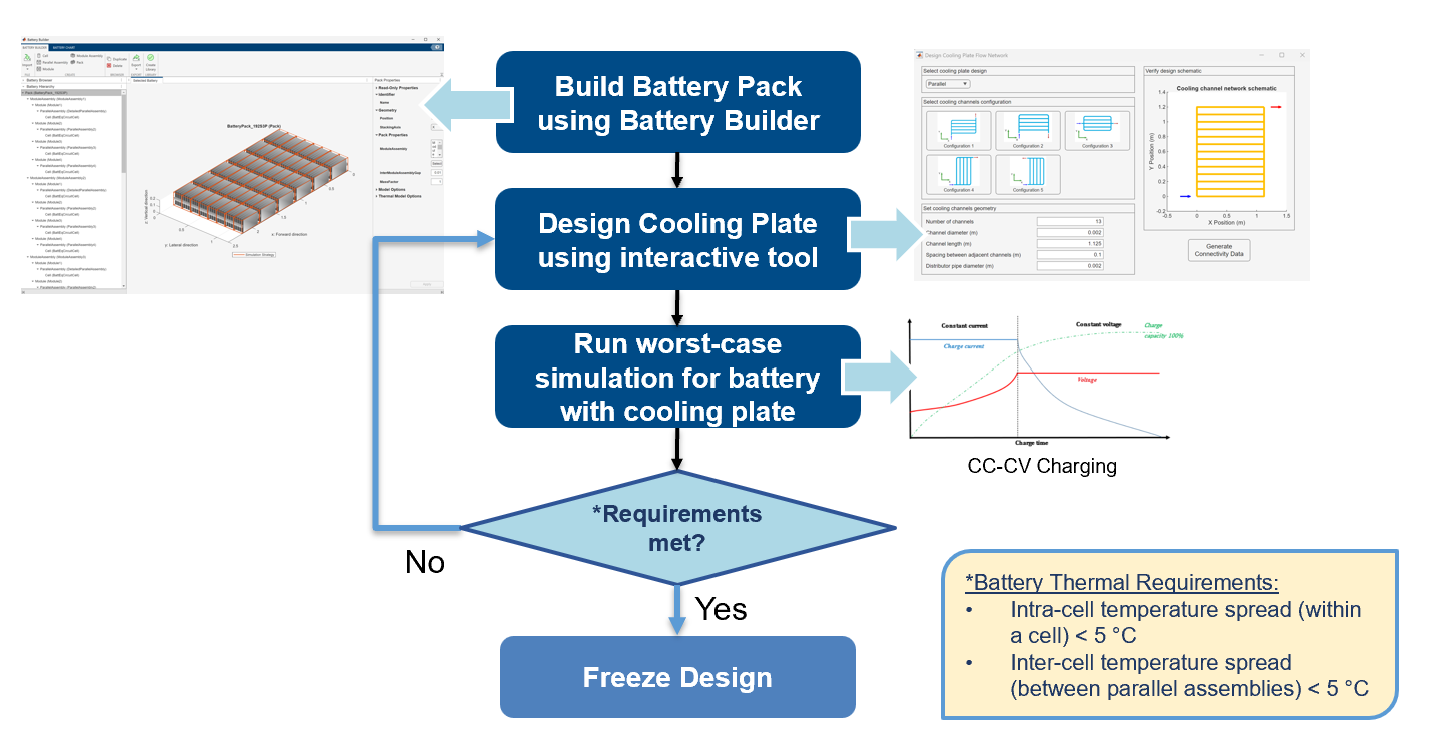

## **Build Battery Pack**

This example uses a battery pack created in the Battery Builder app. To learn how to build the pack using MATLAB, see [Build a 96S3P Battery Pack](matlab:open('..\Scripts\BuildBatteryPackWithCoolingPlate.m')). For more information on building battery packs  using MATLAB and the Battery Builder app, see [Build Simple Model of Battery Pack in MATLAB and Simscape](https://www.mathworks.com/help/simscape-battery/ug/build-battery-pack.html).

Load a battery pack from the library. 

batteryLibName = "BatteryPack96S3P_lib";
batteryPackName = "BatteryPack96S3P";
load_system(batteryLibName);

 Load the design data of the battery pack. This data is generated by the Battery Builder app when you create a Battery `Pack` object library.

batteryData = load("BatteryPack96S3P.mat");

To visualize the battery pack before you build the system model and to view its model resolution, create the figure where you want to visualize your pack and then use the [`batteryChart`](https://www.mathworks.com/help/simscape-battery/ref/simscape.battery.builder.batterychart.html) function. To view the model resolution of the pack, define the `SimulationStrategyVisible` name-value argument as `"On"`.

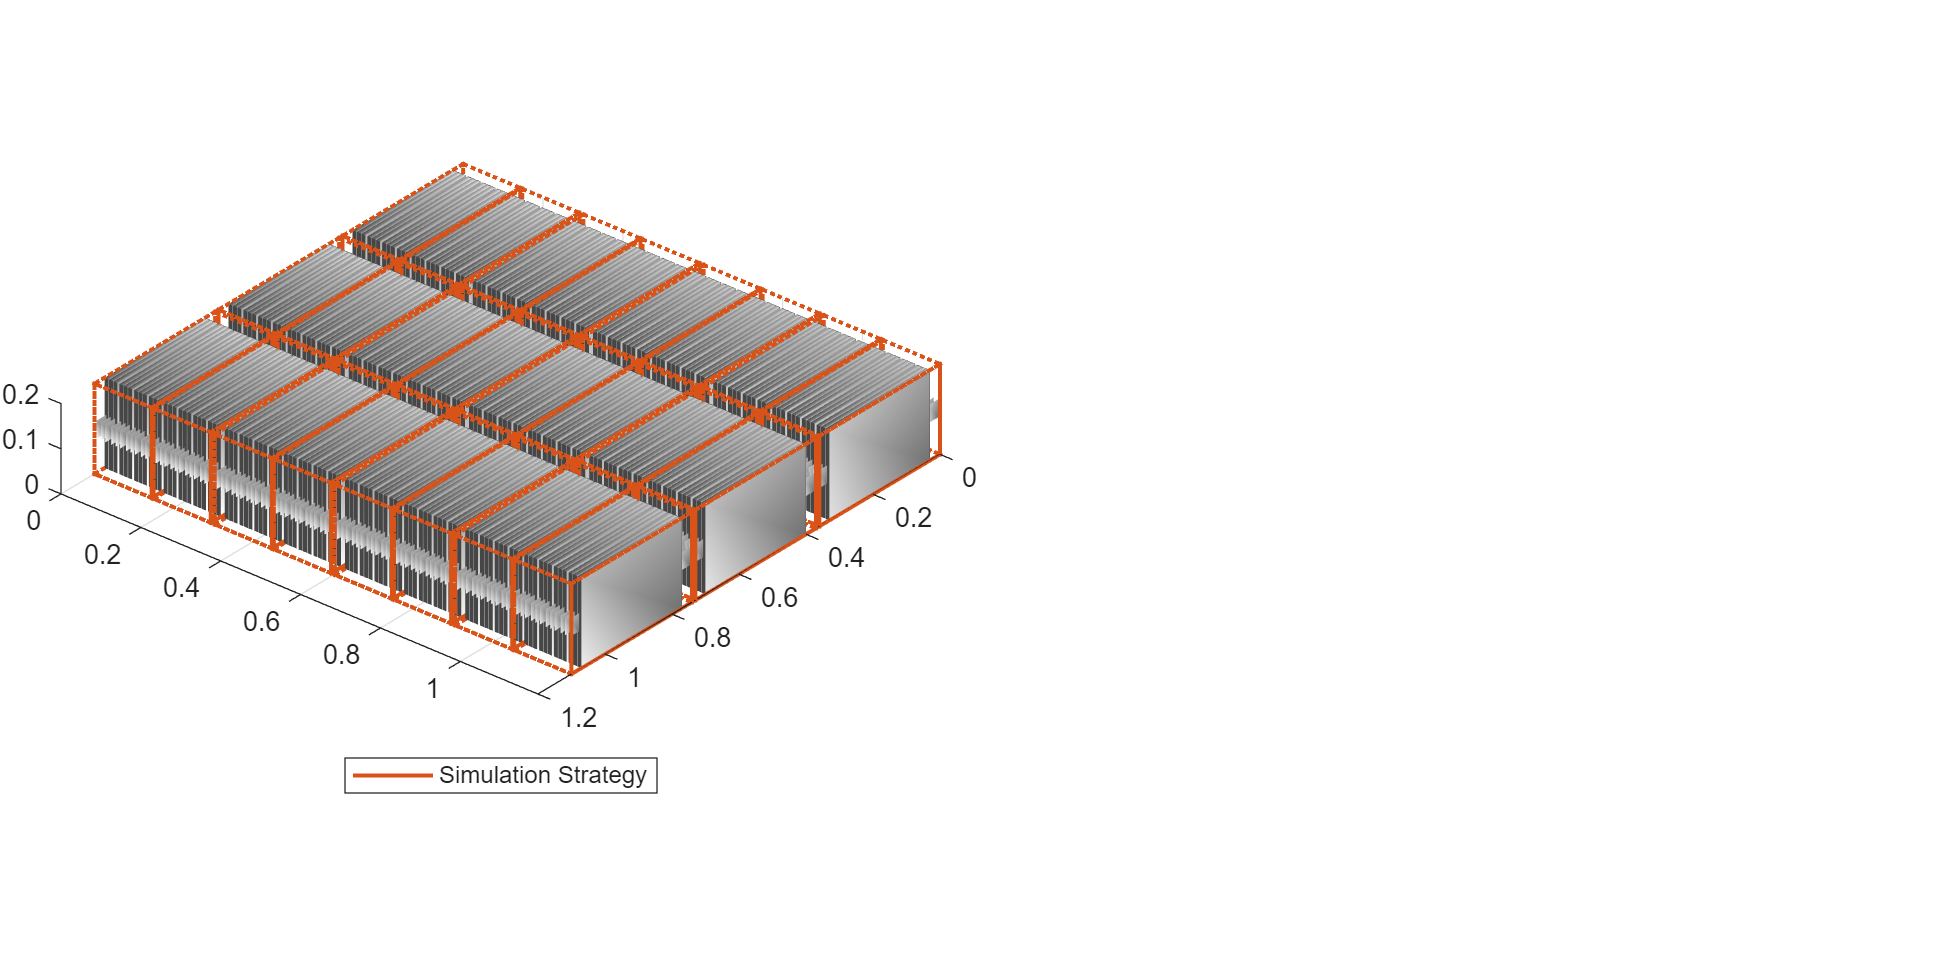

f = figure(Color="w",Position=[0 0 1000 500]);
tl = tiledlayout(1,2,"Parent",f,"TileSpacing","Compact","Padding","tight");
nexttile(tl)
batteryPackData = batteryData.(batteryPackName);
batteryPackChart1 = batteryChart(tl,batteryPackData,SimulationStrategyVisible="On");

Access the information related to the thermal nodes of the battery pack from the loaded design data . Thermal nodes are points on the boundary of a battery assembly that represent thermal connections to the environment or a cooling plate.

Retrieve and store the number of thermal nodes, the interface area dimensions for each thermal node, and the XY locations of the interface areas on the battery assembly surface that connects to the cooling plate.

numBattThermalNodes = batteryPackData.ThermalNodes.Bottom.NumNodes;  
dimBattThermalNodes = simscape.Value(batteryPackData.ThermalNodes.Bottom.Dimensions,"m");
locBattThermalNodes = simscape.Value(batteryPackData.ThermalNodes.Bottom.Locations,"m");
locCoolingPlate = batteryPackData.CoolingPlate;

## Design Cooling Plate

You can interactively create and configure a flow network design for a battery cooling plate. To launch the interactive tool, ensure that the project is loaded, then enter the following at the MATLAB command prompt.

For each design type (Parallel or Serpentine), you can select from a set of available cooling channel configuration templates. To learn how to use this tool, see [Design a Cooling Plate Flow Network Interactively](matlab:open('..\Overview\html\HelpDesignCoolingPlateFlowNetwork.html')).

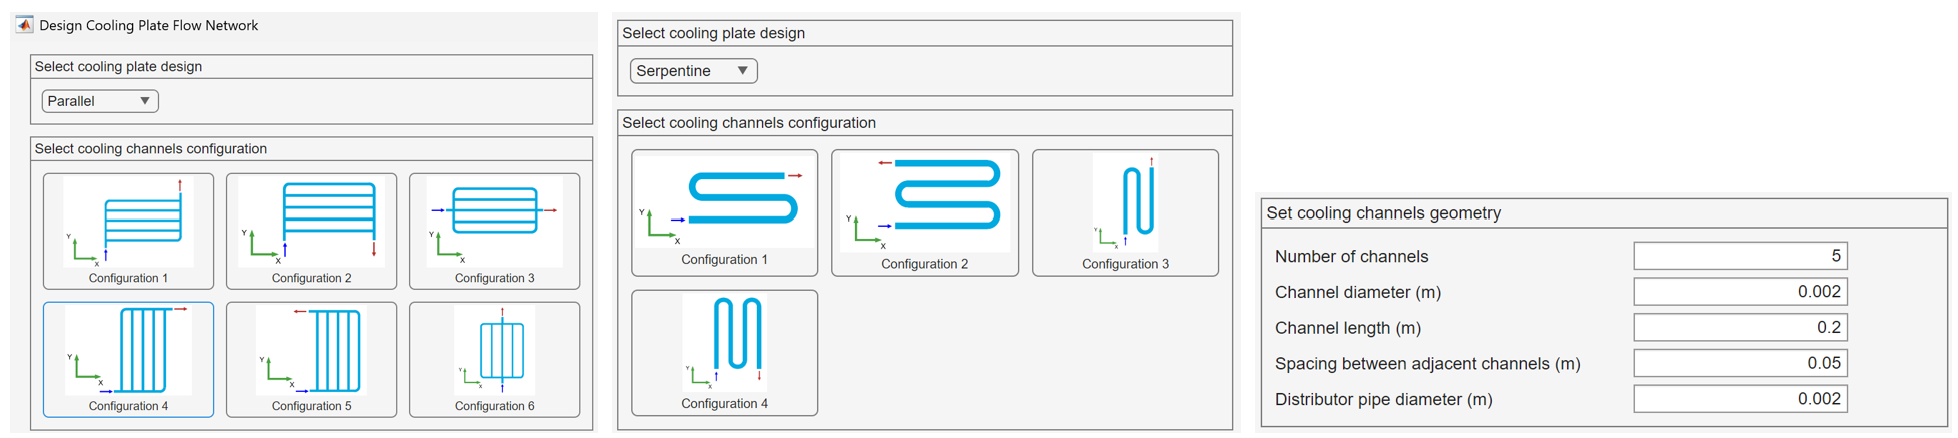

This tool creates a connectivity data structure for a cooling plate flow network. A `ConnectivityData` structure represents the topology (components and their connections) and the geometry (positions, diameters, and optional centerlines) of a battery cooling plate flow network. You can also create a `ConnectivityData` structure manually from scratch. To learn more, see [Connectivity Data](matlab:open('..\Overview\html\HelpConnectivityData.html')).

To load a `ConnectivityData` structure, load the `CoolingPlateFlowConnectivityData.mat`. This example uses a connectivity data structure generated using the interactive design tool. The cooling plate uses `Configuration 1` template for a `Parallel Channel` design. 

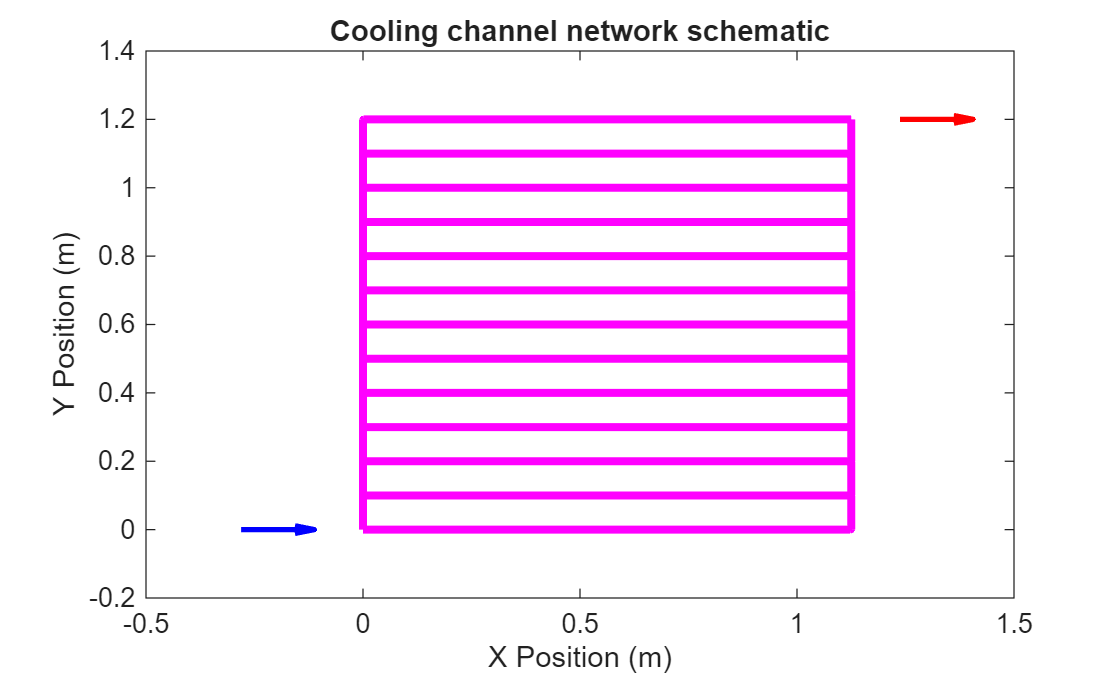

load("CoolingPlate24NFlowConnectivityData.mat");
figure(Name="CoolingChannelFlowNetwork");
plotCoolingChannels(ConnectivityData,Axis=gca,PlotType="2D")

To modify cooling plate material properties such as thickness, thermal conductivity, density, specific heat, or initial temperature, specify the desired property values and pass them as optional arguments when creating the `ComponentConnectivity` object.

thkPlate = simscape.Value(0.008,"m");

To generate a Simscape model of the battery cooling plate, create an instance of the class `ComponentConnectivity.` The instance for the class `ComponentConnectivity` adds the required blocks for the cooling plate flow network in the model, connects them with each other and to the blocks for cooling plate thermal network and battery pack, sets flow and thermal parameters in the model. This generated Simscape model of the cooling plate is saved as a library in the Components folder of the project.

coolingPlateData = ComponentConnectivity(ConnectivityData,numBattThermalNodes,dimBattThermalNodes,...
    locBattThermalNodes,thicknessPlate=thkPlate, numPartitionsX=3, numPartitionsY=8);

## Simulate Worst-Case Scenario

This example uses an integrated model of the battery pack and the generated cooling plate subjected to a CC-CV charging cycle. You can also build a thermal management system with your own battery pack, or module assembly, or modules and custom cooling plate.

To build your own battery thermal management system model, 

- Create a new model. 

- Add your battery pack to the model, or use a pack from the library. 

- Add your cooling plate in the battery pack, or use a cooling plate from the generated library. If the model already contains a cooling plate, replace it with the new one. 

- Apply a CC-CV charging cycle to the battery pack. 

- Add and connect a flow source and a flow sink to the cooling plate.

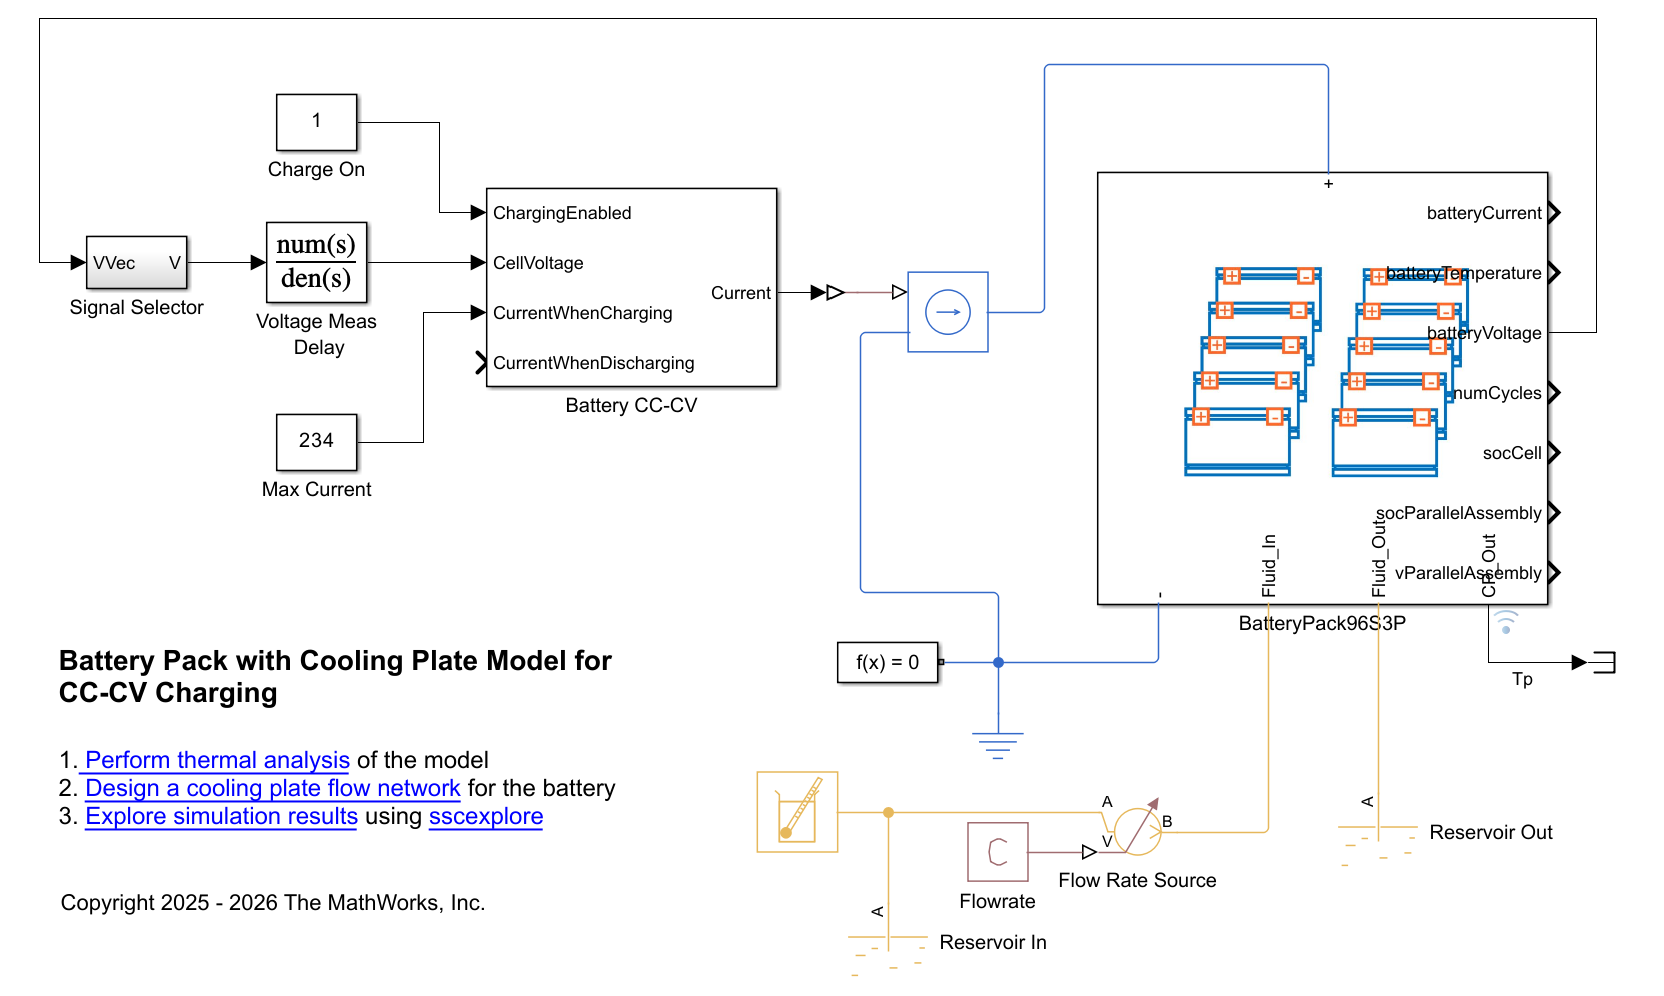

Load the battery thermal management system model.

modelNameBattThermalSys = "PouchBatteryPack96S3PWithCustomCoolingPlateForCharging";
open_system(modelNameBattThermalSys);

To simulate the worst-case scenario, run the function `simulateBatteryAndCoolingPlateWithLoad`. This function 

- Parameterizes the battery modules in the pack, 

- Applies the battery charge cycle parameters in the model.

- Simulates the integrated model for the battery and the cooling plate subjected to a CC-CV charging cycle.

stopTime = 600;
simOut = simulateBatteryAndCoolingPlateWithLoad(modelNameBattThermalSys, ...
    batteryLibName, batteryPackData, stopTime, BattInitialTemperature=simscape.Value(303.15,"K"), ...
    MaxVoltage=simscape.Value(4.1,"V"));

## Analyze Results

Plot battery thermal node temperatures and the cooling plate partition temperatures at any chosen time instant. In this example, four parallel assemblies within a module are grouped into one thermal node, and each cell is discretized into four elements along its height. This plot shows the final thermal node temperatures (at* t = 600 s*) for a battery pack, connected to a parallel-channel cooling plate where coolant enters at bottom-left corner and exits at top-right corner in the XY plane.

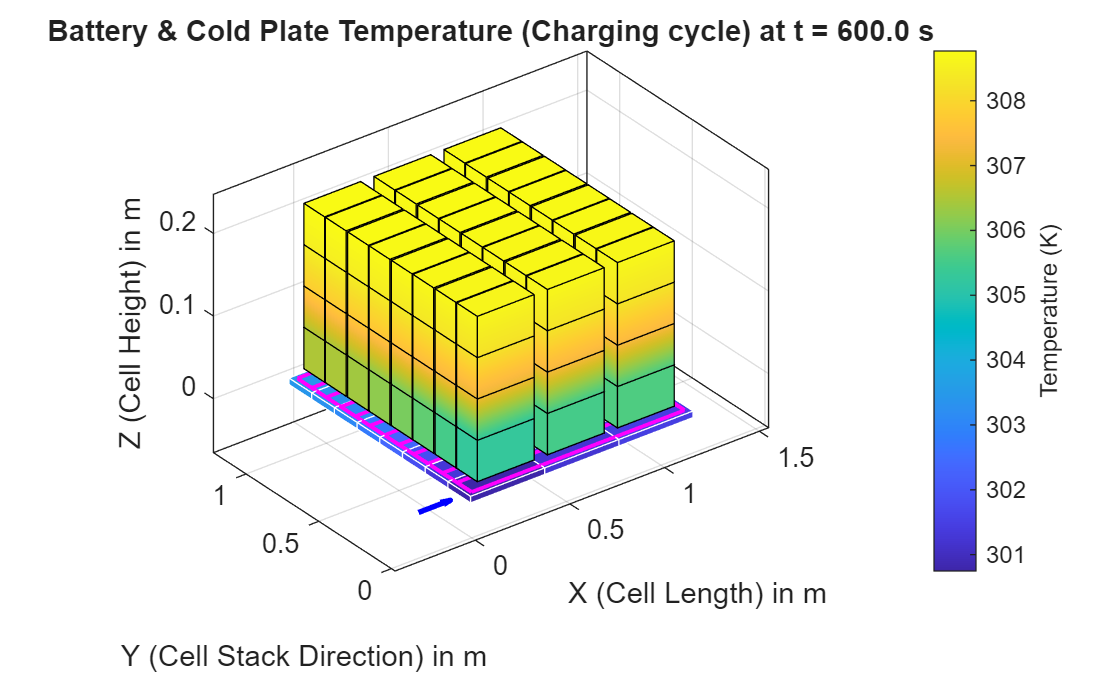

plotBatteryAndPlateTemp3D(simOut.SimlogBattery, batteryPackName, batteryData, ...
    simOut.logsout, coolingPlateData, stopTime, LocationCoolingPlate=locCoolingPlate);
colormap(gca,"parula");
cb = colorbar(gca);
cb.Label.String = 'Temperature (K)';
rotate3d on;

You can plot only the battery thermal node temperatures at any chosen time instant in the YZ plane. This plot shows the final thermal node temperatures (at *t = 600 s*) for the battery pack in the YZ plane, connected to a parallel-channel cooling plate where coolant enters at bottom-left corner and exits at top-right corner in the XY plane.

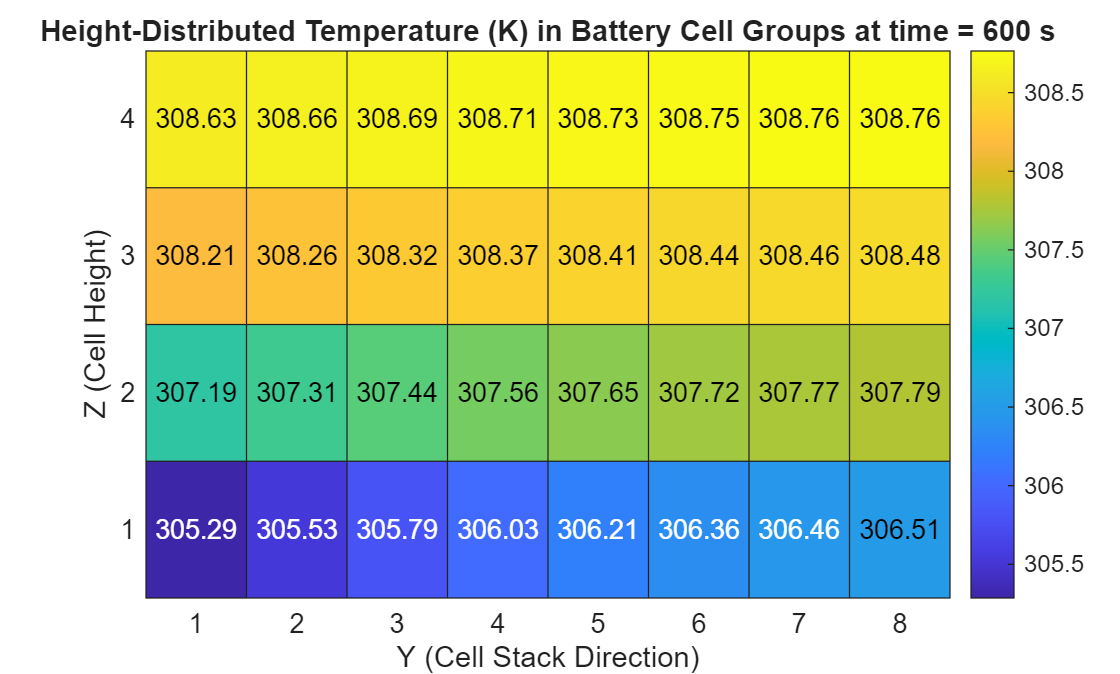

plotModuleAssemblyYZTemp(simOut.SimlogBattery,batteryPackName,"ModuleAssembly1",batteryData,stopTime);

You can plot only the cooling plate partition temperatures at any chosen time instant in the XY plane. This plot shows the final plate partition temperatures (at *t = 600 s*) for a parallel-channel cooling plate in the XY plane where coolant enters at bottom-left corner and exits at top-right corner in the XY plane. 

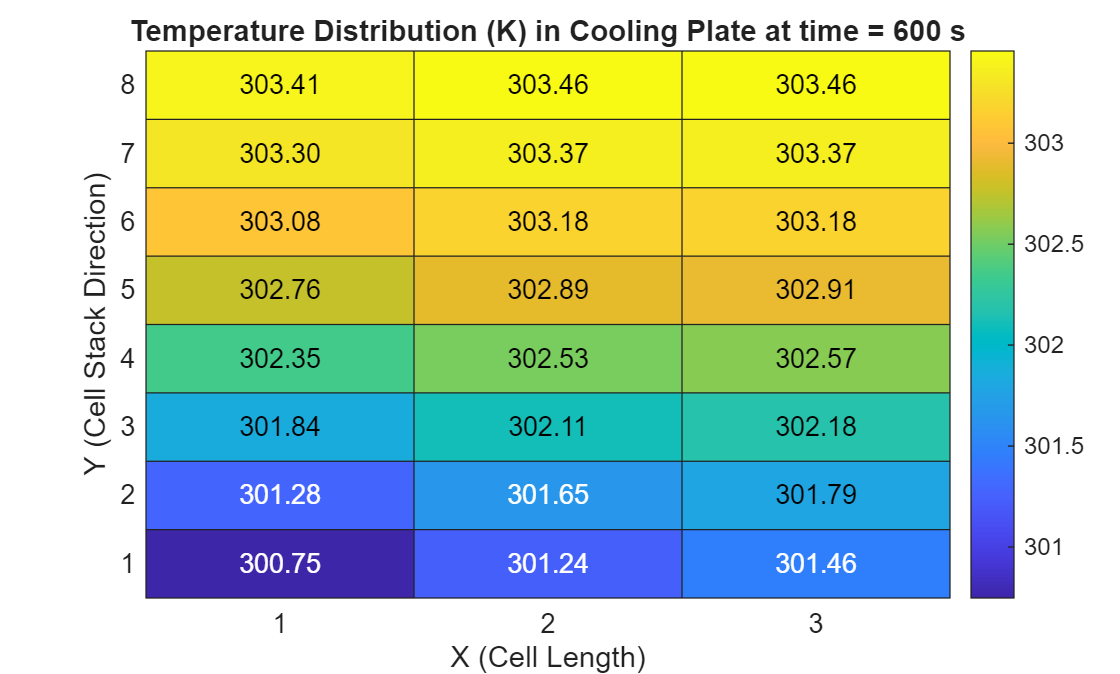

plotPlatePartitionTemp(simOut.logsout,stopTime,NumPartitionsX=3,NumPartitionsY=8);

To visualize how the battery pack and cooling plate partition temperatures change over time, run the function [animateBatteryAndPlateTemp3D](matlab:open('..\utils\animateBatteryAndPlateTemp3D.m')).

## Conclusion

This example evaluates the battery thermal node temperatures at *t* = 600 s. Along the height of the battery, node temperatures range from approximately 305.3 K (32.3 $\degree$C) to 308.6 K (35.6 $\degree$C), resulting in an intra-cell temperature spread of 3.3 $\degree$C. Across the entire battery pack, temperatures vary from approximately 305.3 K (32.3 $\degree$C) to 308.8 K (35.8 $\degree$C), corresponding to an inter-cell temperature spread of 3.5 $\degree$C. For the specified battery geometry, cooling plate design, coolant flow rate, and charging cycle, both thermal requirements are satisfied.

If the thermal limits are violated at any point during the load cycle, you can modify the battery or cooling plate design. You can also perform a trade-off study by varying key design and operating parameters, such as cooling channel diameter, coolant flow rate, and charge rate. This analysis helps identify an optimal design and operating conditions that support long-term battery durability.

Copyright 2025 - 2026 The MathWorks, Inc.